% Load Audio Data
load mtlb;
X = mtlb;

% Resample
X = resample(X,44100,Fs);

% Stereolize & Normalize
X = [X X]/max(X);

% Set Sampling Freq
Fs = 44100;

X = audioread("saw-sweep.wav");
%X = audioread("なんか変になる音程.wav");
soundsc(X,Fs);

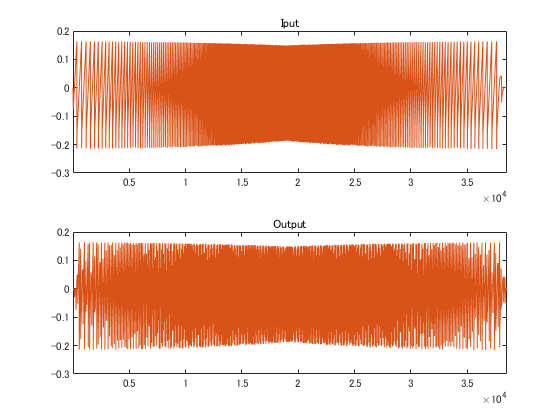

% Create Plugin Instance
p = Plug_SimplePitchShifter();

p.pitch = 12;

% Test Plugin
[~,X,Y_simple] = test_plugin(p,X,Fs,128);

% Plot
figure(1);clf;
tiledlayout("flow");
nexttile;plot(X);title("Iput");
nexttile;plot(Y_simple);title("Output");
xlim([-inf inf]);linkaxes;    

soundsc(Y_simple,Fs);

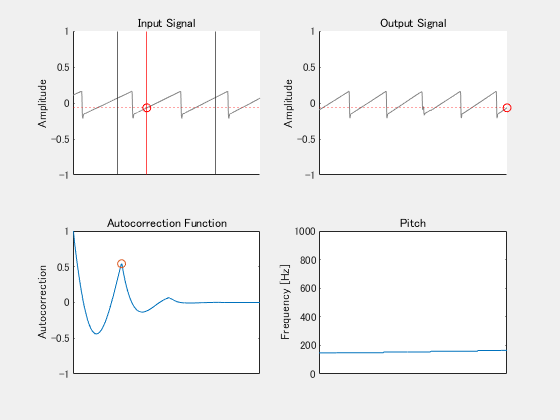

% Create Plugin Instance
p = Plug_PitchShifter();

p.pitch = 6;
p.L = 0;

% Test Plugin
[~,X,Y] = test_plugin(p,X,Fs,16);


% Plot
figure(2);clf;
tiledlayout("flow");
nexttile;plot(X);title("Iput");
nexttile;plot(Y);title("Output");
xlim([-inf inf]);linkaxes;

soundsc(Y,Fs);

%Y_nocrossfade = Y
soundsc(Y_nocrossfade,Fs);

% Test in realtime
test_plugin_realtime(p,Fs,2048,10,false);

audioTestBench Plug_PitchShifter

validateAudioPlugin Plug_PitchShifter

generateAudioPlugin Plug_PitchShifter